La imagen original utilizada para las pruebas es la siguiente:

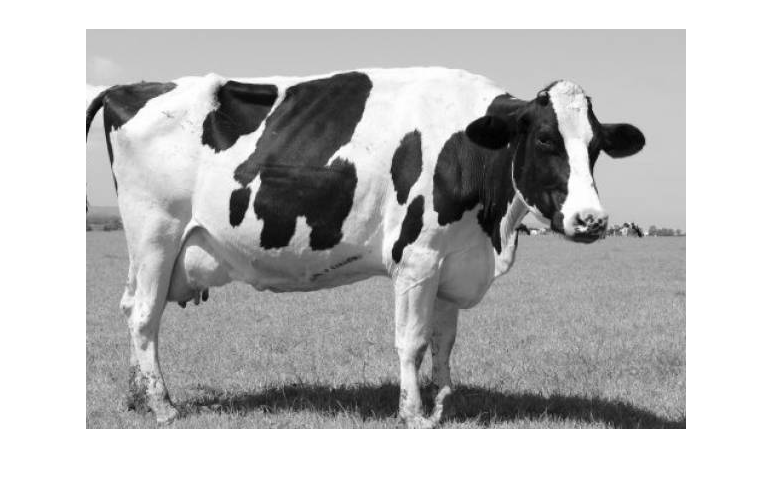

imshow(rgb2gray(imread('./Media/imatge2.jpg')), []);

Ejercicio 1:

I = imread('./Media/imatge2.jpg');
I = rgb2gray(I);
I = imnoise(I,'salt & pepper', 0.02);
I = double(I);
F = Ejercicio_1(I);

Tras la aplicacion del flitro de media aritmetica obtenemos una imagen 'blurred:

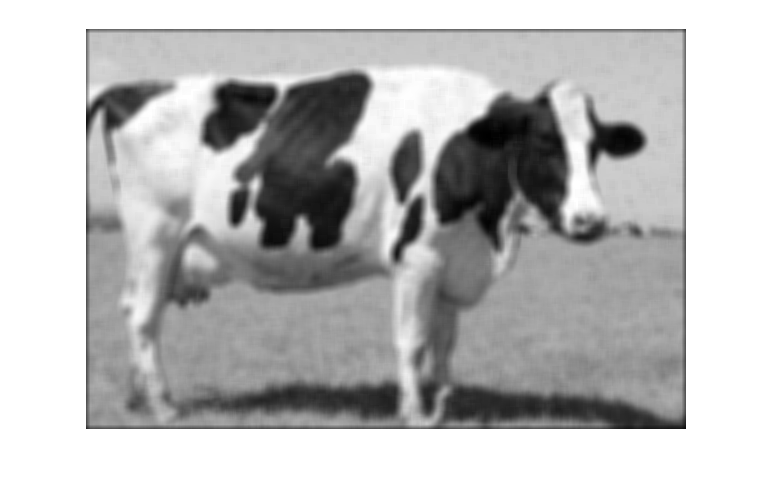

imshow(F, []);

Podemos comparar la imagen anterior con la aplicacion del filtro segun la implementacion de matlab, y como vemos, a pesar de haber realizado el filtro en 2 partes (primero verticalmente y luego horizontalmente), obtenemos el mismo resultado.

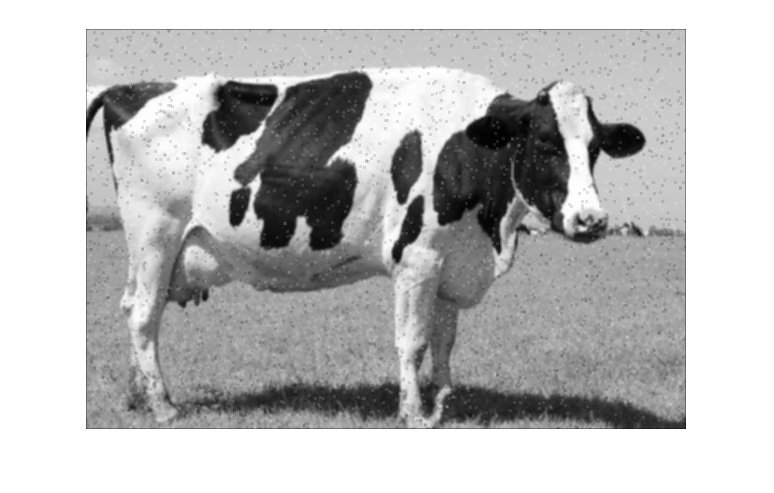

imshow(imfilter(I, fspecial('average',3)), []);

Ejercicio 2:

I = imread('./Media/imatge2.jpg');
I = rgb2gray(I);
I = imnoise(I,'salt & pepper', 0.05);
I = double(I);

Imagen con ruido:

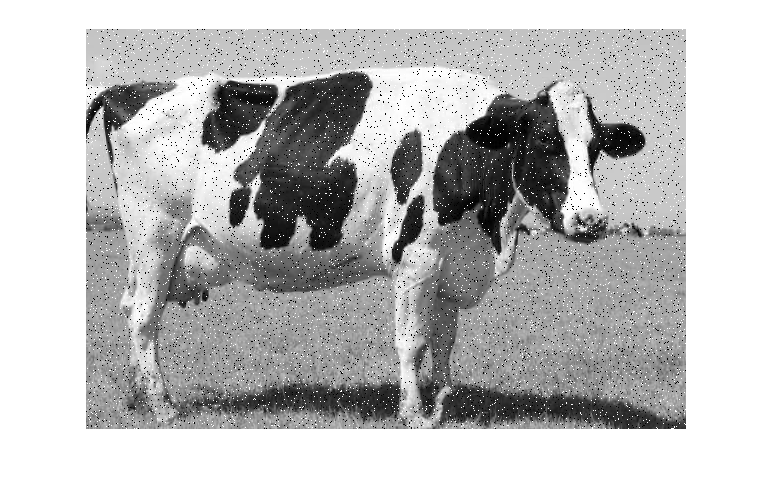

imshow(I, []);

Imagen filtrada:

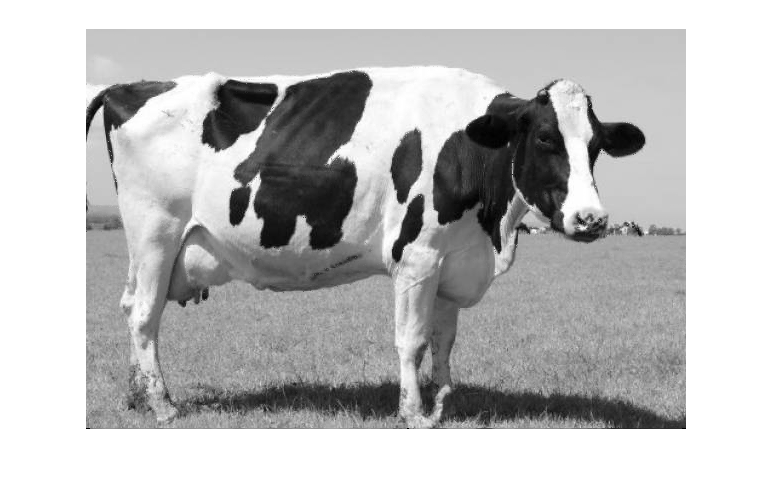

F = colfilt(I, [9 9], 'sliding', @Ejercicio_2);
imshow(F, []);

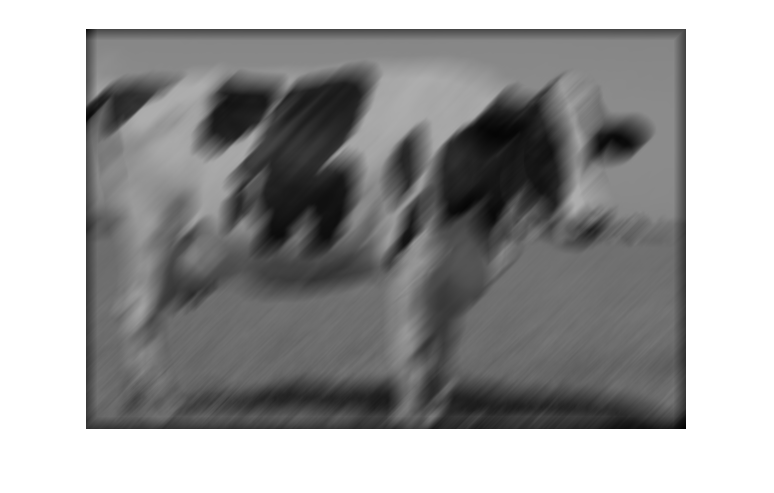

I = imread('./Media/imatge2.jpg');
I = rgb2gray(I);

size= 35;
alpha=45;

H = zeros(size);
H(int32(floor(size)/2),1:size) = 1;
H = H/ceil(size);
H = imrotate(H,alpha);
B = imfilter(I,H);
imshow(B);

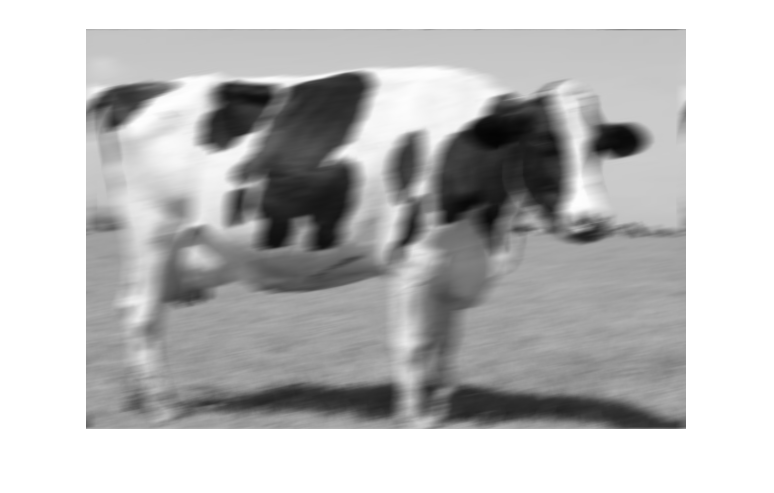

LEN = 21;
THETA = 11;
PSF = fspecial('motion', LEN, THETA);
blurred = imfilter(I, PSF, 'conv', 'circular');
figure, imshow(blurred)

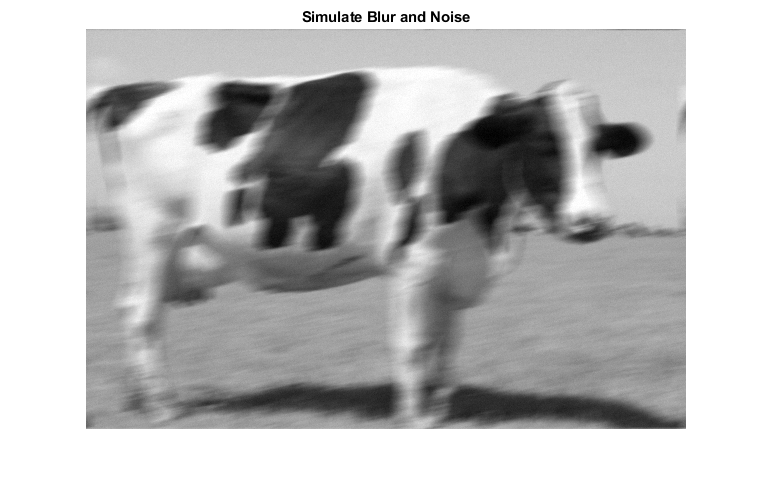



noise_mean = 0;
noise_var = 0.0001;
blurred_noisy = imnoise(blurred, 'gaussian', ...
                        noise_mean, noise_var);
figure, imshow(blurred_noisy)
title('Simulate Blur and Noise')

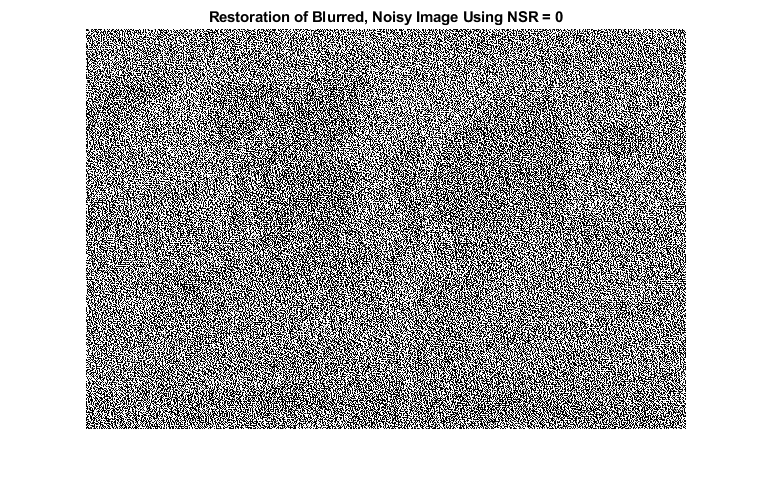


estimated_nsr = 0;
wnr2 = deconvwnr(blurred_noisy, PSF, estimated_nsr);
figure, imshow(wnr2)
title('Restoration of Blurred, Noisy Image Using NSR = 0')


estimated_nsr = noise_var / I;
wnr3 = deconvwnr(blurred_noisy, PSF, estimated_nsr);

Error using deconvwnr
Expected input number 3, NCORR, to be finite.

Error in deconvwnr>parseInputs (line 194)
    validateattributes(varargin{n},{'double'},{'real' 'finite'},...

Error in deconvwnr (line 81)
    parseInputs(varargin{:});

figure, imshow(wnr3)
title('Restoration of Blurred, Noisy Image Using Estimated NSR');